G1 =4/9; G2 =-4; G3 = -1/2;
U01 = [0,0]';
U02 = [1,0]';
U03 = [3/2,1]';
U0 = [U01,U02,U03];
T = 12.6;
N =200000;
h = T/(N-1);
time = 0:h:T;
U1evalut(:,1) = U0(:,1);
U2evalut(:,1) = U0(:,2);
U3evalut(:,1) = U0(:,3);
for i = 2:N
    U0 = RK4(h,U0,@Uevolution,@fun,G1,G2,G3);
    U1evalut(:,i) = U0(:,1);
    U2evalut(:,i) = U0(:,2);
    U3evalut(:,i) = U0(:,3);
end


plot(U1evalut(1,:),U1evalut(2,:)); hold on
plot(U2evalut(1,:),U2evalut(2,:));
plot(U3evalut(1,:),U3evalut(2,:));
hold off

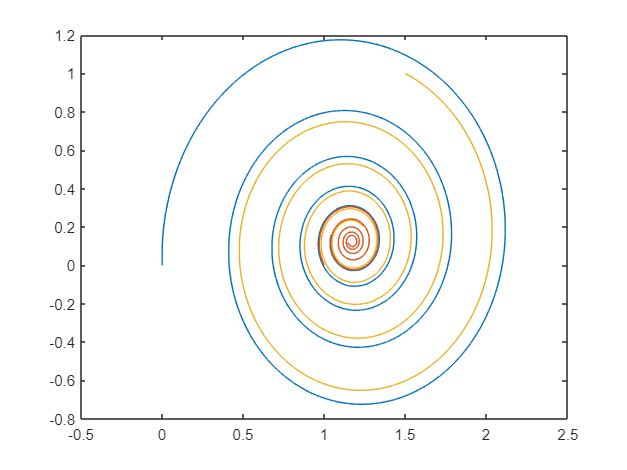

Ns = 2.^(13:18);

errors = zeros(1,2);
j = 1;
for N = Ns
    G1 =4/9; G2 =-4; G3 = -1/2;
    U01 = [0,0]';
    U02 = [1,0]';
    U03 = [3/2,1]';
    U0 = [U01,U02,U03];
    T = 12.6;
    h = T/(N-1);
    
    myU1evalut(:,1) = U0(:,1);
    myU2evalut(:,1) = U0(:,2);
    myU3evalut(:,1) = U0(:,3);
    for i = 2:N
        U0 = RK4(h,U0,@Uevolution,@fun,G1,G2,G3);
        myU1evalut(:,i) = U0(:,1);
        myU2evalut(:,i) = U0(:,2);
        myU3evalut(:,i) = U0(:,3);
    end
    
    errors(j) = norm(myU1evalut(:,end) - U1evalut(:,end))+...
                norm(myU2evalut(:,end) - U2evalut(:,end))+...
                norm(myU3evalut(:,end) - U3evalut(:,end));
    j = j+1;
end

loglog(T./Ns,errors);
hold on
%loglog((T./Ns).^4,errors);
hold off


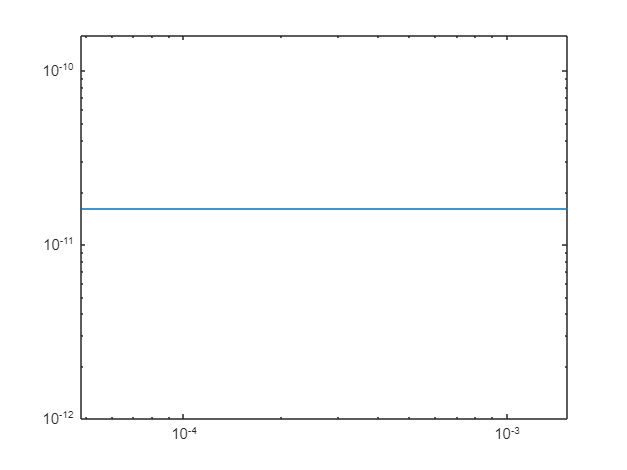

function res = RK4(h,U,fun,fun2,G1,G2,G3)
    k1 = fun(U,fun2,G1,G2,G3);

    k2 = fun(U + 1/4 *k1*h,fun2,G1,G2,G3);

A =    -11   100
     1   -11


ans =    -1.0000
  -21.0000


    k3 = fun(U + 3/32 *k1*h + 9/32*k2*h,fun2,G1,G2,G3);
    k4 = fun(U +1932/2197 *k1*h -7200/2197 *k2*h + 7296/2197 * k3*h,fun2,G1,G2,G3);
    k5 = fun(U +439/216 *k1*h - 8*k2*h+3680/513*k3*h -845/4104*k4*h,fun2,G1,G2,G3);
    k6 = fun(U -8/27*k1*h + 2*k2*h - 3544/2565*k3*h + 1859/4104*k4*h - 11/40*k5*h,fun2,G1,G2,G3);
    res = U + h*(25/216*k1 + 1408/2565*k3+2197/4104*k4-1/5*k5);
    %res = U + h*(16/135*k1 + 6656/12825*k3 + 28561/56430*k4 - 9/50*k5 + 2/55*k6);
end
function res = RK5(h,U,fun)
    k1 = fun(U);
    k2 = fun(U + 1/4 *k1*h);
    k3 = fun(U + 3/32 *k1*h + 9/32*k2*h);
    k4 = fun(U +1932/2197 *k1*h -7200/2197 *k2*h + 7296/2197 * k3*h);
    k5 = fun(U +439/216 *k1*h - 8*k2*h+3680/513*k3*h -845/4104*k4*h);
    k6 = fun(U -8/27*k1*h + 2*k2*h - 3544/2565*k3*h + 1859/4104*k4*h - 11/40*k5*h);
    %res = U + h*(25/216*k1 + 1408/2565*k3+2197/4104*k4-1/5*k5);
    res = U + h*(16/135*k1 + 6656/12825*k3 + 28561/56430*k4 - 9/50*k5 + 2/55*k6);
end
function res = Uevolution(U,fun,G1,G2,G3)
    Point1 = U(:,1);
    Point2 = U(:,2);
    Point3 = U(:,3);
    
    
    newPoint1 = fun(Point1,Point2,Point3,G2,G3);
    newPoint2 = fun(Point2,Point3,Point1,G3,G1);
    newPoint3 = fun(Point3,Point2,Point1,G2,G1);
    res = [newPoint1,newPoint2,newPoint3];
end

function res = fun(Point,Point2,Point3,G1,G2)
    dP1 = Point-Point2;
    dx = dP1(1);
    dy = dP1(2);

    %G1 = Point2(3);

    Unx = -(G1/(2*pi) *dy/(dx^2 +dy^2));
    Uny = (G1/(2*pi) *dx/(dx^2 +dy^2));
    preRes = [Unx,Uny]';

    dP2 = Point-Point3;
    dx = dP2(1);
    dy = dP2(2);

    %G2 = Point3(3);

    Unx = -(G2/(2*pi) *dy/(dx^2 +dy^2));
    Uny = (G2/(2*pi) *dx/(dx^2 +dy^2));
    res = preRes+[Unx,Uny]';

end